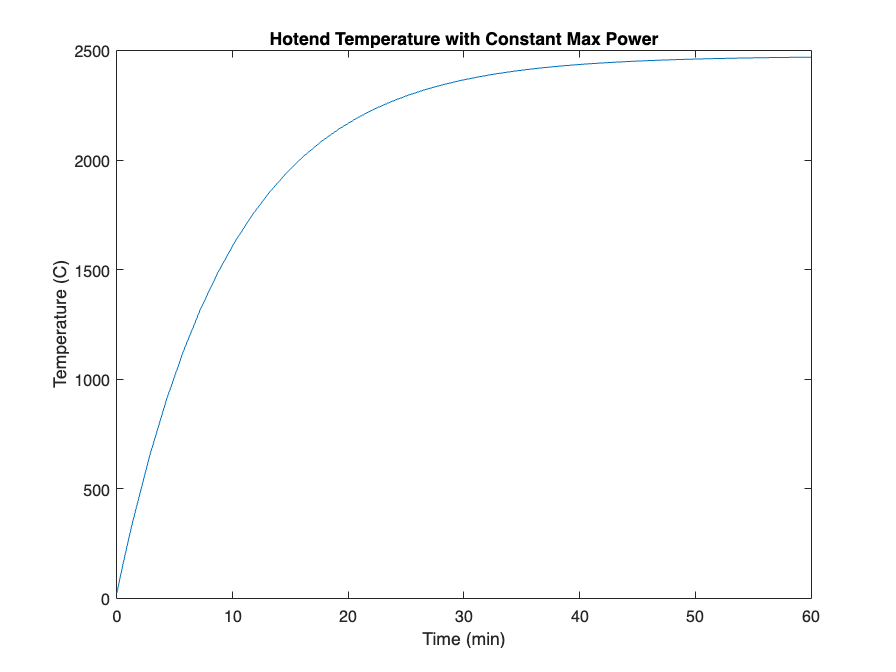

% Theoretical Models
clear
clf

% Constant Material Parameters
k_s = 0.3;          % W/(m*K), thermal conductivity of silicone (estimate)
L_s = .0015;        % m, silicone thickness
h_s = 12.9;         % W/(m^2*K), heat transfer coefficient of silicone
A_s =.00173104;     % m^2, external surface area of silicone
A_sb =.00118045;    % m^2, contact area of block and silicone
c_b = 389;          % J/(kg*K), specific heat of block
m_b =.03023;        % kg, mass of block (including nozzle)
m_s = .00255;       % kg, mass of silicone  
T_air = 296.25;     % K, ambient air temperature
T_r = 200;          % K, goal temperature
T_initial = 296.15; % K, initial temperature
Q_in = 50;          % W, input power from heating cartridge #TODO update desc

% User parameters
T_request = 210 + 273.15; % K, requested temperature of the hotend

% PID parameters
Kp = 23.713;
Ki = 1.34; 
Kd = 104.932;
integral = 0;
last_time = -0.1;
last_error = T_request-296.15;
i = 0;

% Thermal Resistance
R_total = L_s / (k_s * A_sb) + 1 / (h_s * A_s);


% Constant Max Power
yspan = [0 60*60];
dTdt_steady = @(t, T_c) 1/(c_b*m_b) * ((T_air - T_c)/R_total + Q_in);
[y,Y] = ode45(dTdt_steady, yspan, T_initial);

figure(1)
plot(y/60,Y-273.15) % convert time to minutes, temp to C
xlabel("Time (min)")
ylabel("Temperature (C)")
title("Hotend Temperature with Constant Max Power")

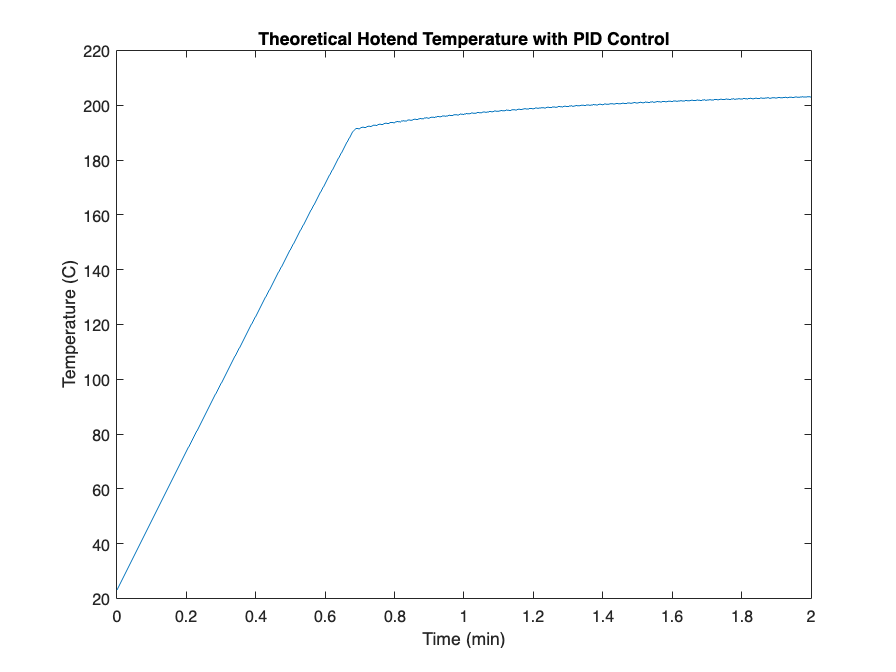


% PID Control
% options = odeset("OutputFcn",@heater_power,"OutputSel",[1]); % # TODO update passed components of soln
options = odeset("MaxStep", 1);
tspan = [0 2*60];
[t,T] = ode45(@(t,T) blockTemp(t, T, Q_in, c_b, T_air, R_total, Kp, Ki, Kd, T_request, m_b, last_error, integral, last_time), tspan, T_initial, options);

figure(2)
plot(t/60,T-273.15) % convert time to minutes, temp to C
xlabel("Time (min)")
ylabel("Temperature (C)")
title("Theoretical Hotend Temperature with PID Control")

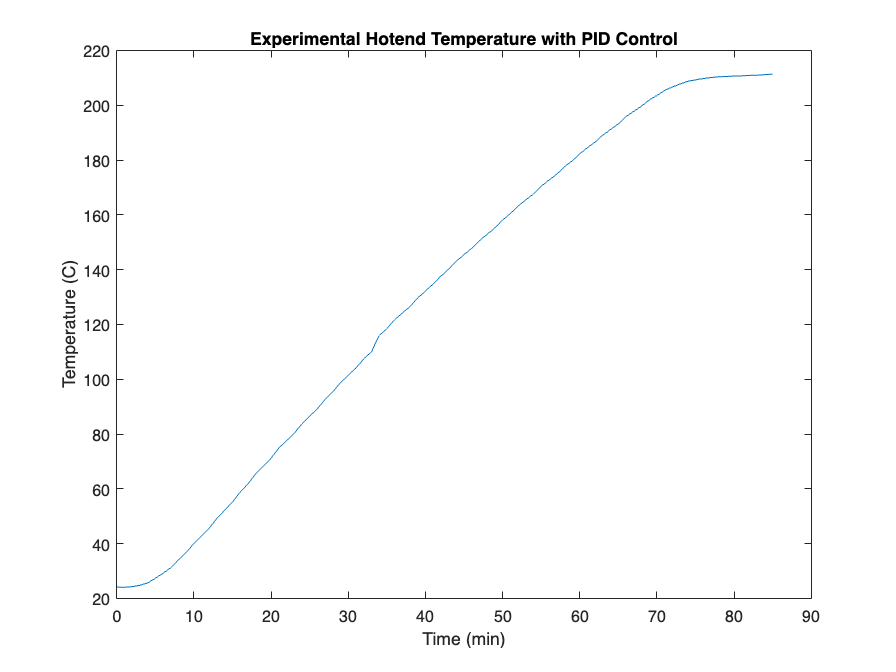

% Experimental Data
test_data = csvread("hotend_testing.csv");
exp_times = 0:85; % time in experimental data

figure(3)
plot(exp_times, test_data(:,2))
title("Experimental Hotend Temperature with PID Control")
xlabel("Time (min)")
ylabel("Temperature (C)")

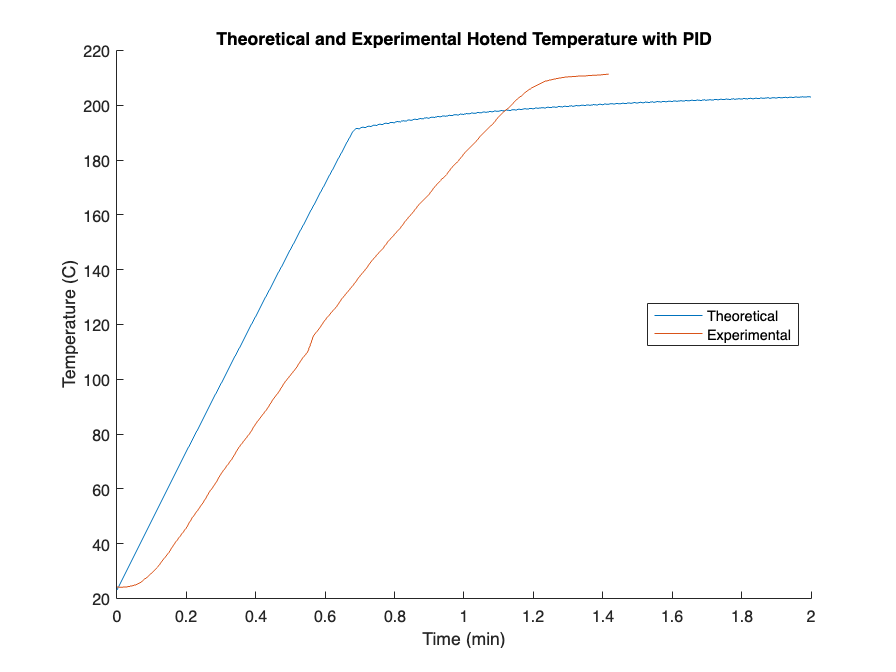

% Compare Theoretical and Experimental PID
figure(4)
hold on
plot(t/60,T-273.15)
plot(exp_times/60,test_data(:,2))
hold off
title("Theoretical and Experimental Hotend Temperature with PID")
xlabel("Time (min)")
ylabel("Temperature (C)")
legend("Theoretical", "Experimental", 'Location','east')

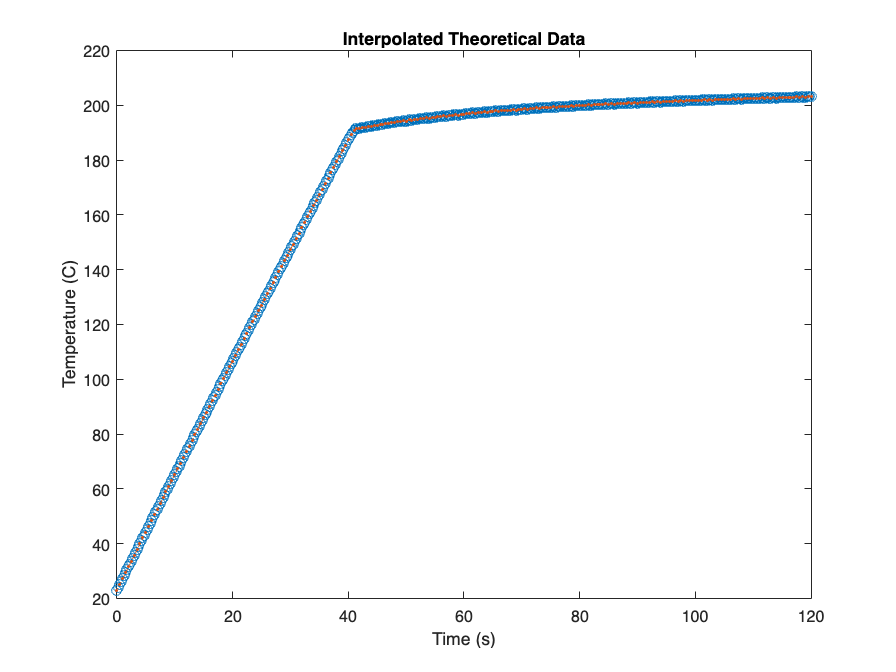

% Interpolation
interp_time = 0:0.5:120;

% Interpolate Theoretical Data
thr_temp = T-273.15;

figure(5)
interp_thr = interp1(t,thr_temp,interp_time);
plot(t,thr_temp,'o',interp_time,interp_thr,':.');
xlim([0 120]);
title('Interpolated Theoretical Data');
xlabel("Time (s)")
ylabel("Temperature (C)")

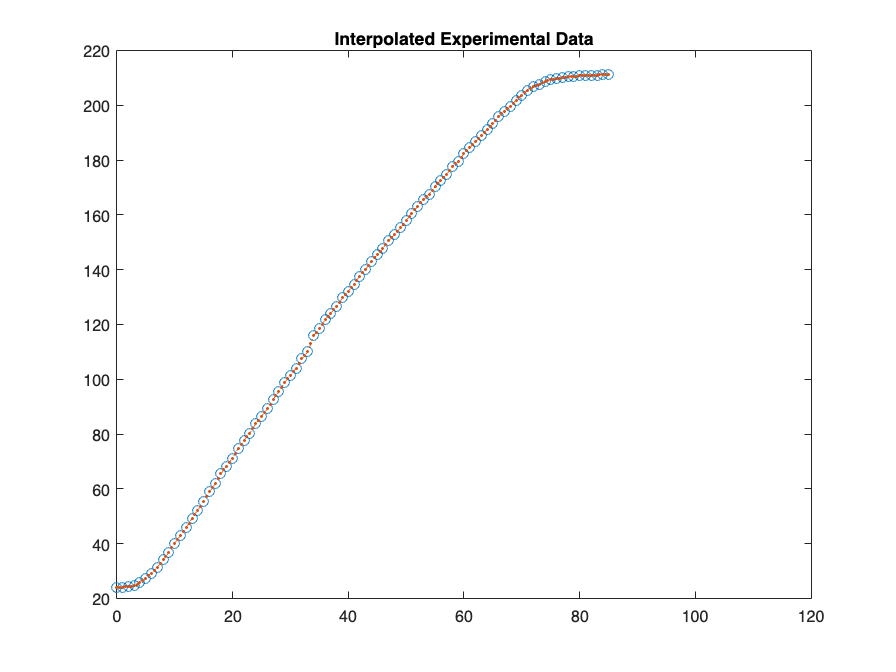

% Interpolate Experimental Data
exp_temp = test_data(:,2);
interp_exp = interp1(exp_times,exp_temp,interp_time);

figure(6)
plot(exp_times,exp_temp,'o',interp_time,interp_exp,':.');
xlim([0 120]);
title('Interpolated Experimental Data');

% Error Analysis
interp_index_to_time = 0:.5:85;
difference = (interp_thr(1:171)-interp_exp(1:171));
percent_error = abs(difference)./interp_exp(1:171);
avg_percent_error = mean(percent_error(1:171))

avg_percent_error = 0.2965

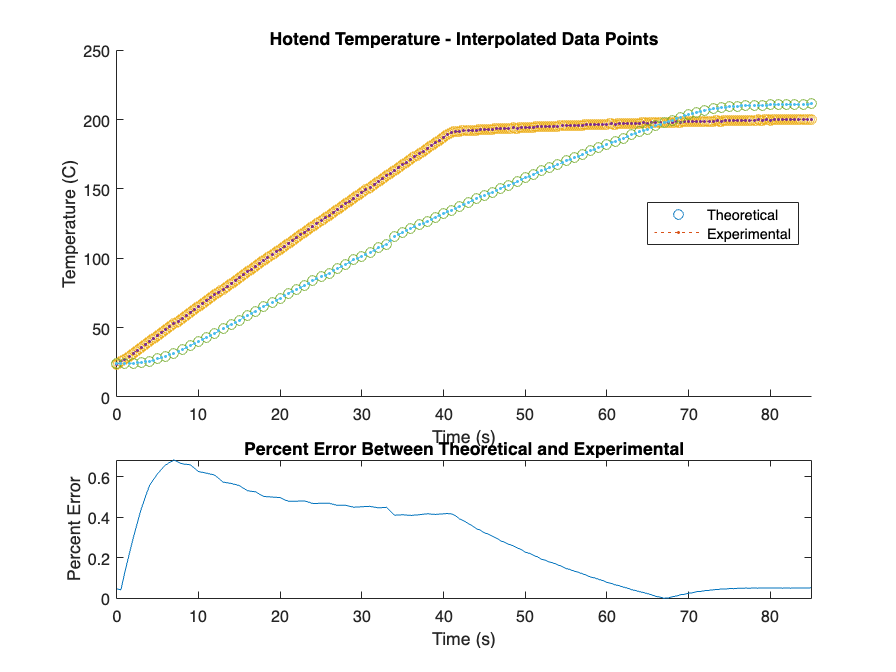

figure(7)
subplot(3,1,[1 2])
hold on
plot(t,thr_temp,'o',interp_time,interp_thr,':.');
plot(exp_times,exp_temp,'o',interp_time,interp_exp,':.');
title("Hotend Temperature - Interpolated Data Points")
legend("Theoretical", "Experimental", 'Location','east')
xlabel("Time (s)")
ylabel("Temperature (C)")
xlim([0 85]);
hold off
subplot(3,1,3)
plot(interp_index_to_time, percent_error)
title("Percent Error Between Theoretical and Experimental")
xlabel("Time (s)")
ylabel("Percent Error")
xlim([0 85]);

function dTdt = blockTemp(t, T, Q_in, c_b, T_air, R_total, Kp, Ki, Kd, T_request, m_b, last_error, integral, last_time)
    time_step = t - last_time;
    error = T_request - T;
    integral = 0;
    derivative = (error - last_error)/time_step; % Ensure this is zero for the first time step
    Q_in = max(min(Kp*error+Ki*integral+Kd*derivative,50),0);
    dTdt = 1/(c_b*m_b) * ((T_air - T)/R_total + Q_in);
    last_error = error;
    last_time = t;
end
